# Community detection and Correlation between brain maps

% Set pwd
cd '' 

% Set path to functions
functionRoot = '';
addpath(fullfile(functionRoot, 'bdl-mapper-v2-main'));
addpath(fullfile(functionRoot, '2019_03_03_BCT'));

rng("default")

% Create custom diverging colormap (blue → white → red)
nColors = 256;
half = nColors / 2;
blue_to_white = [linspace(0, 1, half)', linspace(0, 1, half)', ones(half,1)];
white_to_red  = [ones(half,1), linspace(1, 0, half)', linspace(1, 0, half)'];
rwb_cmap = [blue_to_white; white_to_red];

% Define the list of labels as a cell array of character vectors
labels = {'L1', 'L2', 'E2', 'R1', 'S1', 'R2', 'W5', 'W7', 'W8', 'W1', 'W3', 'W4', 'W6', 'W2', 'E1', 'G1', 'G2', 'S2', 'M1', 'M2', 'M3', 'M4', 'M5', 'M6'};
labels = sort(labels) % Sort the labels alphabetically

labels = 1×24 cell array
    {'E1'}    {'E2'}    {'G1'}    {'G2'}    {'L1'}    {'L2'}    {'M1'}    {'M2'}    {'M3'}    {'M4'}    {'M5'}    {'M6'}    {'R1'}    {'R2'}    {'S1'}    {'S2'}    {'W1'}    {'W2'}    {'W3'}    {'W4'}    {'W5'}    {'W6'}    {'W7'}    {'W8'}



% Load parcel and community info
parcelsT = readtable('Shine_375_labels.csv');
shine_network = parcelsT(1:347,4);

## 1a) Community detection

## Specify cohort 1 or 2

cohort = 1;

if cohort == 1
    data = readtable('ddfactors_subs1_nog_hcp.xlsx');
    suffix = '1';
elseif cohort == 2
    data = readtable('ddfactors_subs2_nog_hcp.xlsx');
    suffix = '2';
else
    disp('Specify cohort');
end

## Loading and demeaning data

rowNames = data{:, 1};
data(:, 1) = [];
data.Properties.RowNames = rowNames;
data = data{:, :}; %turns the table into an array

% demean participants based on individual scores
subject_ids = cellfun(@(x) split(x, '_'), rowNames, 'UniformOutput', false);
subject_ids = cellfun(@(x) x{2}, subject_ids, 'UniformOutput', false);
subject_ids_numeric = cellfun(@str2double, subject_ids);

data_zscore_subjwise = [];
for s = 1:1:max(subject_ids_numeric)
    tmp = find(subject_ids_numeric==s);
    data_zscore_subjwise = [data_zscore_subjwise; zscore(data(tmp,:))];

end
data = data_zscore_subjwise;

% check for dead columns
bad_columns = find(var(data) == 0)


bad_columns =

  1×0 empty double row vector



data(:,bad_columns) = [];

column_variances = var(data, 0, 1); 

## Louvain community detection (don't have to rerun if output saved)

rng("default")
[ciu, q, d] = community_louvain_iterative(corr(data'),'negative_asym',1,1000);
max(ciu)
% save(sprintf('rdochcp_allsubs%s_community.mat', suffix), 'ciu', 'q', 'd');

## 1b) After communities saved, load files specific to cohort 1 or 2

if cohort == 1
    load('rdochcp_allsubs1_community.mat');
    suffix = '1';
elseif cohort == 2
    load('rdochcp_allsubs2_community.mat');
    suffix = '2';
else
    disp('Specify cohort');
end

## Calculate module centroids and visualize communities over data

% Calculate module centroids
num_communities = max(ciu) % 4/5 modules for cohort 1/2 respectively

num_communities = 4

comm_centroid = zeros(num_communities, size(data, 2));

% Compute the centroids
for comm = 1:num_communities
    % Get the indices of rows belonging to the current community (binary)
    community_indices = ciu == comm;
    
    % Compute the mean of rows for the current community
    comm_centroid(comm, :) = mean(data(community_indices, :), 1);
end
% save(sprintf('comm_centroid%s.mat', suffix), 'comm_centroid');

% Visualize community output
[comm, comm2, ~] = arrangeComm(ciu, corr(data'));
imagesc(comm)
% saveas(gcf, sprintf('figures/rdoc_allsubs%s_community_hm.png', suffix));

## Metrics of communities

% Build symmetric correlation matrix
W = corr(data');                
W(isnan(W)) = 0;
W(1:size(W,1)+1:end) = 0;       % zero diagonal
W = (W + W')/2;                 % enforce symmetry

% Parameters
T = 1000;                       % number of iterations
gamma = 1;                      % resolution parameter

% Storage for results
ciu = zeros(size(W,1), T);      % community assignments
Q   = zeros(T,1);               % modularity scores

% Optional: reproducibility
rng("default")
seeds = randi(1e9, T, 1);

% Loop over runs
for t = 1:T
    rng(seeds(t)); 
    [ciu(:,t), Q(t)] = community_louvain(W, gamma, [],'negative_asym'); 
end

% Compute agreement matrix and consensus
A = agreement(ciu) / T;
c_cons = consensus_und(A, 0.5, 1000);

% Example: ARI between each run and consensus
ARI_cons = arrayfun(@(k) rand_index(c_cons, ciu(:,k), 'adjusted'), 1:T);
mean_consensus_ARI = mean(ARI_cons);
sd_consensus_ARI   = std(ARI_cons);

fprintf('Consensus communities: %d\n', numel(unique(c_cons)));
fprintf('ARI to consensus: mean=%.3f, SD=%.3f\n', mean_consensus_ARI, sd_consensus_ARI);

## Metrics for community assignment: Probability, Entropy, and Dominant Proportion

% Build subject x community contingency table (counts)
nSubj = max(subject_ids_numeric);
nComm = max(ciu);
tab = accumarray([subject_ids_numeric(:), ciu(:)], 1, [nSubj, nComm]);  % rows=subjects, cols=communities

% Convert to per-subject probabilities
rowSums = sum(tab,2);
p = tab ./ max(rowSums,1); % safe divide; subjects with zero rows remain zeros

% Subject-wise entropy (base-2) and dominant proportion
pp = p;
pp(pp<=0) = 1;                         % 0*log2(1)=0, avoids -Inf
subj_entropy = -sum(p .* log2(pp), 2); % higher = more spread across communities
max_prop = max(p, [], 2);              % higher = concentrated in one community

% Optional: dominant community index per subject (for sorting/inspection)
[~, dom_comm] = max(p, [], 2);

%% Summary statistics
mean_entropy = mean(subj_entropy, 'omitnan');
median_entropy = median(subj_entropy, 'omitnan');
mean_maxprop = mean(max_prop, 'omitnan');
median_maxprop = median(max_prop, 'omitnan');
fprintf('Subjects: %d | Communities: %d\n', nSubj, nComm);
fprintf('Entropy: mean=%.3f, median=%.3f (max possible = log2(%d)=%.3f)\n', ...
    mean_entropy, median_entropy, nComm, log2(nComm));
fprintf('Dominant proportion: mean=%.3f, median=%.3f\n', mean_maxprop, median_maxprop);

%% Visualization
% Sort subjects by dominant community, then by dominant proportion (descending)
[~, sort_idx] = sortrows([dom_comm, -max_prop]);
tab_sorted = tab(sort_idx, :);

tiledlayout(2,2, 'Padding','compact', 'TileSpacing','compact');

% Heatmap: subject x community counts
nexttile([2 1]); % tall heatmap
imagesc(tab_sorted);
axis tight; box on;
xlabel('Community'); ylabel('Subject (sorted)');
title('Subject × Community: assignment counts');
colorbar;

% Histogram of dominant proportion
nexttile;
histogram(max_prop, 20, 'Normalization','pdf');
xlabel('Proportion in dominant community'); ylabel('Density');
title('Subject concentration (max proportion)'); box on;

% Histogram of entropy
nexttile;
histogram(subj_entropy, 20, 'Normalization','pdf');
xlabel('Shannon entropy (bits)'); ylabel('Density');
title('Subject dispersion across communities'); box on;

## 2) Correlation between general factor and Margulies gradients

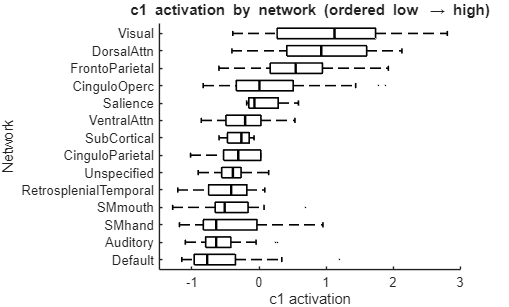

M = readmatrix('Margulies_5gradients.csv');

c1 = readmatrix('g_avg_sub1_shine.xlsx', 'Range', 'B2:B348')'; 
c2 = readmatrix('g_avg_sub2_shine.xlsx', 'Range', 'B2:B348')';
p_bs1 = readmatrix('brainssmash_sa_corrected_pvals_gfactor1_Margulies.csv');
p_bs2 = readmatrix('brainssmash_sa_corrected_pvals_gfactor2_Margulies.csv');

% FDR correction (Benjamini-Hochberg) for each p-value matrix
p_bs1_fdr = mafdr(p_bs1(:), 'BHFDR', true);
p_bs1_fdr = reshape(p_bs1_fdr, size(p_bs1));

p_bs2_fdr = mafdr(p_bs2(:), 'BHFDR', true);
p_bs2_fdr = reshape(p_bs2_fdr, size(p_bs2));

stars1 = makeStars(p_bs1_fdr);   
stars2 = makeStars(p_bs2_fdr);   

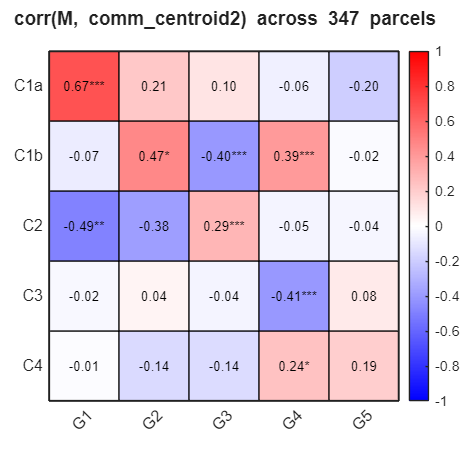


% Correlation matrices (rows vs rows; correlation across 347 parcels)
R1 = corr(c1', M', 'Rows','pairwise');  % 5 x 4
R2 = corr(c2', M', 'Rows','pairwise');  % 5 x 5

% Labels
xlabels_g  = arrayfun(@(k) sprintf('G%d',k), 1:5, 'UniformOutput', false);
ylabels_c1 = {"G"};
ylabels_c2 = {"G"};

% Appearance
cell_size = 70;
n = 256;
cmap = [linspace(0,1,n/2)', linspace(0,1,n/2)', ones(n/2,1); ...
        ones(n/2,1), linspace(1,0,n/2)', linspace(1,0,n/2)'];
colormap(cmap); 
caxis([-1 1]);

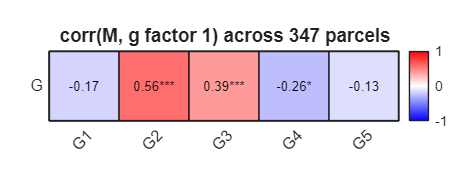

clim = [-1 1];            % symmetric
fig_pos = [100 100];      % [left top] in pixels
linewidth = .5;

plot_fixed_square_heatmap_with_stars(R1, stars1, xlabels_g, ylabels_c1, ...
    'corr(M, g factor 1) across 347 parcels', ...
    fig_pos, cell_size, cmap, clim, ...
    'figures/corr_M_vs_g1.png', linewidth);

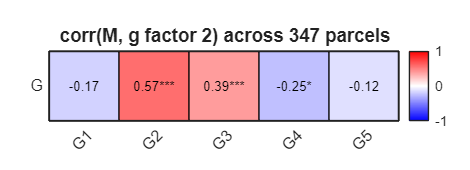


plot_fixed_square_heatmap_with_stars(R2, stars2, xlabels_g, ylabels_c2, ...
    'corr(M, g factor 2) across 347 parcels', ...
    fig_pos, cell_size, cmap, clim, ...
    'figures/corr_M_vs_g2.png', linewidth);

## 3) Boxplot of networks in general factor (Fig. 3e)

c1 = c1(:);                                     % 347x1
net = table2array(shine_network(:,1));          % extract the single column
net = categorical(net);                         % group labels

% Order networks by central tendency of c1 (median) low → high
[G, netCats] = findgroups(net);
netMedian = splitapply(@median, c1, G);
[~, idx] = sort(netMedian, 'ascend');
netOrder = netCats(idx);
net = reordercats(net, string(netOrder));

% Replace "None" with "Unspecified"
net = renamecats(net, 'None', 'Unspecified');

% Horizontal boxplots grouped by network (black, visible)
cats = string(categories(net));  % preserves your reordercats order
figure('Color','w');

h = boxplot(c1, net, ...
    'Orientation','horizontal', ...
    'PlotStyle','traditional', ...
    'GroupOrder', cellstr(cats), ...
    'Colors','k', ...
    'Symbol','.', ...        % show outliers as small black dots (or '' to hide)
    'Widths',0.6, ...
    'Whisker',1.5);

% Ensure all elements are clearly visible and black
set(h, 'LineWidth', 1.2);
set(findobj(gca,'Tag','Box'),      'Color','k', 'LineWidth',1.2);
set(findobj(gca,'Tag','Median'),   'Color','k', 'LineWidth',1.8);
set(findobj(gca,'Tag','Whisker'),  'Color','k', 'LineWidth',1.2);
set(findobj(gca,'Tag','Outliers'), 'MarkerEdgeColor',[0 0 0], 'MarkerSize',3);
set(findobj(gca,'Tag','Upper Whisker EndCap'), 'Color','k', 'LineWidth',1.2);
set(findobj(gca,'Tag','Lower Whisker EndCap'), 'Color','k', 'LineWidth',1.2);

xlabel('c1 activation');
ylabel('Network');
title('c1 activation by network (ordered low \rightarrow high)');
grid off;  box off; 
% xline(0,'k:');

set(gcf, 'PaperPositionMode','auto');   % preserve size on export
% print(gcf, 'figures/c1_by_network_boxplot', '-dpdf', '-painters'); % Vector format (recommended)
% print(gcf, 'figures/c1_by_network_boxplot', '-dpng', '-r300'); % Or high-resolution PNG (300 dpi)

## 4) Correlation between Community centroids and Margulies gradients

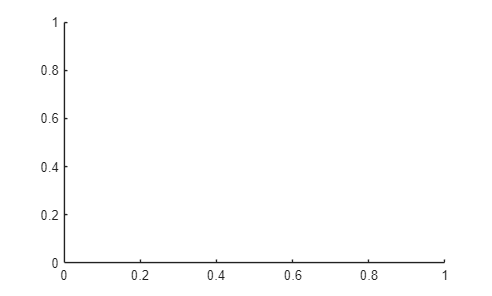

M = readmatrix('Margulies_5gradients.csv');
c1 = readmatrix('comm_centroid_shine.csv')'; 
c2 = readmatrix('comm_centroid2_shine.csv')';
c2([2, 3, 4, 5], :) = c2([5, 3, 2, 4], :);

p_bs1 = readmatrix('brainssmash_sa_corrected_pvals_C1_Margulies.csv');
p_bs2 = readmatrix('brainssmash_sa_corrected_pvals_C2_Margulies.csv');
p_bs2([2, 3, 4, 5], :) = p_bs2([5, 3, 2, 4], :);

% FDR correction (Benjamini-Hochberg) for each p-value matrix
p_bs1_fdr = mafdr(p_bs1(:), 'BHFDR', true);
p_bs1_fdr = reshape(p_bs1_fdr, size(p_bs1));

p_bs2_fdr = mafdr(p_bs2(:), 'BHFDR', true);
p_bs2_fdr = reshape(p_bs2_fdr, size(p_bs2));

stars1 = makeStars(p_bs1_fdr);   % size should be 4x5 (to match R1)
stars2 = makeStars(p_bs2_fdr);   % size 5x5 (to match R2)

% Correlation matrices (rows vs rows; correlation across 347 parcels)
R1 = corr(c1', M', 'Rows','pairwise');  % 5 x 4
R2 = corr(c2', M', 'Rows','pairwise');  % 5 x 5

% Labels
xlabels_g  = arrayfun(@(k) sprintf('G%d',k), 1:5, 'UniformOutput', false);
ylabels_c1 = {"C1", "C2", "C3", "C4"};
ylabels_c2 = {"C1a", "C1b", "C2", "C3", "C4"};

% Appearance
cell_size = 70;
n = 256;
cmap = [linspace(0,1,n/2)', linspace(0,1,n/2)', ones(n/2,1); ...
        ones(n/2,1), linspace(1,0,n/2)', linspace(1,0,n/2)'];
colormap(cmap); 
caxis([-1 1]);

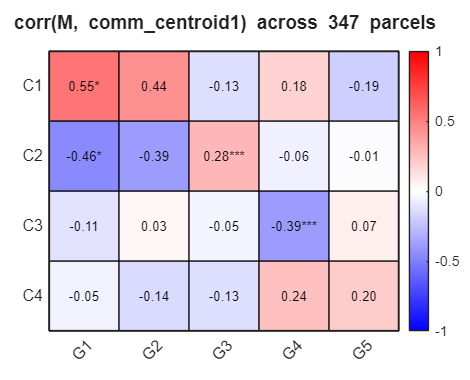

clim = [-1 1];            % symmetric
fig_pos = [100 100];      % [left top] in pixels
linewidth = .5;

plot_fixed_square_heatmap_with_stars(R1, stars1, xlabels_g, ylabels_c1, ...
    'corr(M, comm\_centroid1) across 347 parcels', ...
    fig_pos, cell_size, cmap, clim, ...
    'figures/corr_M_vs_commC1.png', linewidth);

Subjects: 412 | Communities: 4


Entropy: mean=1.834, median=1.918 (max possible = log2(4)=2.000)


Dominant proportion: mean=0.419, median=0.400


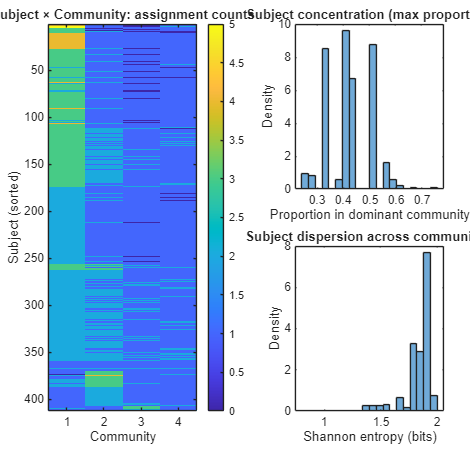


plot_fixed_square_heatmap_with_stars(R2, stars2, xlabels_g, ylabels_c2, ...
    'corr(M, comm\_centroid2) across 347 parcels', ...
    fig_pos, cell_size, cmap, clim, ...
    'figures/corr_M_vs_commC2.png', linewidth);

## 5) Correlation of community centroid fscores for validation

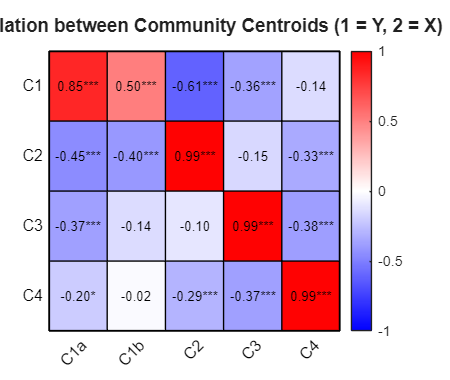

% Fscores from Community Centroids
load('comm_centroid1.mat'); % fscores 
load('comm_centroid2.mat'); % fscores 
comm_centroid2([2, 3, 4, 5], :) = comm_centroid2([5, 3, 2, 4], :);

p_bs1 = readmatrix('brainsmash_sa_corrected_p_values_hm1.csv');

% Reordering as the original cohort 2 C5 matches cohort 1 C1, so its changed to 1b
p_bs1(:, [2, 3, 4, 5]) = p_bs1(:, [5, 3, 2, 4]); 

p_bs2 = readmatrix('brainsmash_sa_corrected_p_values_hm2.csv');
p_bs3 = readmatrix('brainsmash_sa_corrected_p_values_hm3.csv');

% Correlate comm_centroid1 and comm_centroid2
n_comm1 = size(comm_centroid1, 1);  % 4 communities (Y-axis)
n_comm2 = size(comm_centroid2, 1);  % 5 communities (X-axis)

R = zeros(n_comm1, n_comm2);  % Dimensions: [Y x X]
P = zeros(n_comm1, n_comm2);

for i = 1:n_comm1
    for j = 1:n_comm2
        [r, p] = corr(comm_centroid1(i,:)', comm_centroid2(j,:)');
        R(i,j) = r;
        P(i,j) = p;
    end
end

P = p_bs1; %replacing the p-value with spatial-autocorrelation corrected values from brainsmash

% Round correlations
R_rounded = round(R, 2);

% Create significance stars
stars = strings(size(P));
stars(P < 0.05) = "*";
stars(P < 0.01) = "**";
stars(P < 0.001) = "***";

% Axis labels
xlabels = {'C1a', 'C1b', 'C2', 'C3', 'C4'};   % comm_centroid2
ylabels = {'C1', 'C2', 'C3', 'C4'};   % comm_centroid1

% Use shared plotting function
plot_fixed_heatmap(R_rounded, stars, xlabels, ...
    'Correlation between Community Centroids (1 = Y, 2 = X)', ...
    [400, 400], rwb_cmap);

% Set Y-axis labels manually
ax = gca;
set(ax, 'YTickLabel', ylabels);

% save_figure_highres(gcf, 'figures/comm_centroid_correlation1', 300);

## 6) Correlation of community centroids and factors from RDoC-Neurovault

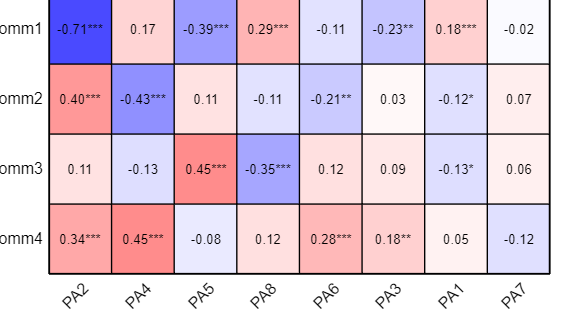

comm_centroid = comm_centroid1;

dd_fscores = readtable('RDoC R01 aim2/dd_cbfa_fscores_nog_forbrainsmash.csv');
rdoc_fscores = readtable('RDoC R01 aim2/rdoc_bicfa_fscores_forbrainsmash.csv');

% Setup dimensions
n_comm = size(comm_centroid, 1);
n_cbfa = size(dd_fscores, 2);
n_rdoc = size(rdoc_fscores, 2);

% Initialize results
R1 = zeros(n_comm, n_cbfa);
P1 = zeros(n_comm, n_cbfa);
R2 = zeros(n_comm, n_rdoc);
P2 = zeros(n_comm, n_rdoc);

% Correlation + p-values
for i = 1:n_comm
    for j = 1:n_cbfa
        [r, p] = corr(comm_centroid(i,:)', dd_fscores{:,j});
        R1(i,j) = r;
        P1(i,j) = p;
    end
    for j = 1:n_rdoc
        [r, p] = corr(comm_centroid(i,:)', rdoc_fscores{:,j});
        R2(i,j) = r;
        P2(i,j) = p;
    end
end

% Round and create stars
R1_rounded = round(R1, 2);
R2_rounded = round(R2, 2);

% FDR correction (Benjamini-Hochberg) for each p-value matrix
p_bs2_fdr = mafdr(p_bs2(:), 'BHFDR', true);
p_bs2_fdr = reshape(p_bs2_fdr, size(p_bs2));

p_bs3_fdr = mafdr(p_bs3(:), 'BHFDR', true);
p_bs3_fdr = reshape(p_bs3_fdr, size(p_bs3));

P1 = p_bs2_fdr; %replacing the p-value with spatial-autocorrelation corrected values from brainsmash
P2 = p_bs3_fdr; %replacing the p-value with spatial-autocorrelation corrected values from brainsmash

stars1 = strings(size(P1));
stars1(P1 < 0.05) = "*";
stars1(P1 < 0.01) = "**";
stars1(P1 < 0.001) = "***";

stars2 = strings(size(P2));
stars2(P2 < 0.05) = "*";
stars2(P2 < 0.01) = "**";
stars2(P2 < 0.001) = "***";

% Reorder R1 and related variables by total absolute correlation per column
[~, col_order1] = sort(sum(abs(R1)), 'descend');
R1_sorted = R1_rounded(:, col_order1);
stars1_sorted = stars1(:, col_order1);
dd_labels_sorted = dd_fscores.Properties.VariableNames(col_order1);

[~, col_order1] = sort(sum(abs(R2)), 'descend');
R2_sorted = R2_rounded(:, col_order1);
stars2_sorted = stars2(:, col_order1);
rdoc_labels_sorted = rdoc_fscores.Properties.VariableNames(col_order1);

% Plot heatmaps
plot_fixed_heatmap(R1_sorted, stars1_sorted, dd_labels_sorted, ...
    'Correlation: comm\_centroid vs dd\_cbfa\_fscores\_nog', [100, 100], rwb_cmap);

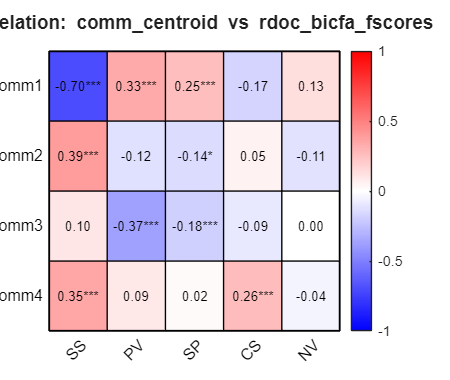

% save_figure_highres(gcf, 'figures/commcentroid_x_ddcbfafscores', 300);

plot_fixed_heatmap(R2_sorted, stars2_sorted, rdoc_labels_sorted, ...
    'Correlation: comm\_centroid vs rdoc\_bicfa\_fscores', [800, 100], rwb_cmap);

% save_figure_highres(gcf, 'figures/commcentroid_x_rdocbicfafscores', 300);

## Same plots for cohort 2

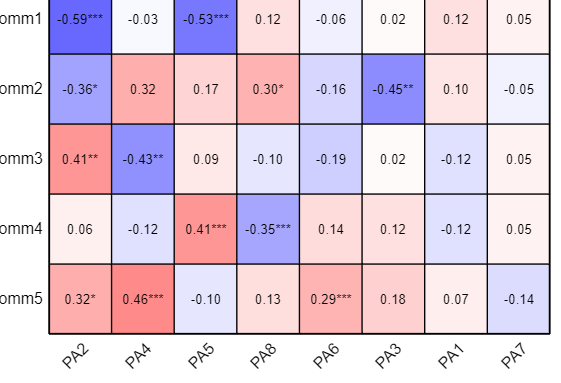

comm_centroid = comm_centroid2;

p_bs2_sub2 = readmatrix('brainssmash_sa_corrected_p_values_hm2_sub2.csv');
p_bs3_sub2 = readmatrix('brainssmash_sa_corrected_p_values_hm3_sub2.csv');

% Setup dimensions
n_comm = size(comm_centroid, 1);
n_cbfa = size(dd_fscores, 2);
n_rdoc = size(rdoc_fscores, 2);

% Initialize results
R1 = zeros(n_comm, n_cbfa);
P1 = zeros(n_comm, n_cbfa);
R2 = zeros(n_comm, n_rdoc);
P2 = zeros(n_comm, n_rdoc);

% Correlation + p-values
for i = 1:n_comm
    for j = 1:n_cbfa
        [r, p] = corr(comm_centroid(i,:)', dd_fscores{:,j});
        R1(i,j) = r;
        P1(i,j) = p;
    end
    for j = 1:n_rdoc
        [r, p] = corr(comm_centroid(i,:)', rdoc_fscores{:,j});
        R2(i,j) = r;
        P2(i,j) = p;
    end
end

% Round and create stars
R1_rounded = round(R1, 2);
R2_rounded = round(R2, 2);

p_bs2_sub2([2, 3, 4, 5], :) = p_bs2_sub2([5, 3, 2, 4], :);
p_bs3_sub2([2, 3, 4, 5], :) = p_bs3_sub2([5, 3, 2, 4], :);

% FDR correction (Benjamini-Hochberg) for each p-value matrix
p_bs2_sub2_fdr = mafdr(p_bs2_sub2(:), 'BHFDR', true);
p_bs2_sub2_fdr = reshape(p_bs2_sub2_fdr, size(p_bs2_sub2));

p_bs3_sub2_fdr = mafdr(p_bs3_sub2(:), 'BHFDR', true);
p_bs3_sub2_fdr = reshape(p_bs3_sub2_fdr, size(p_bs3_sub2));

P1 = p_bs2_sub2_fdr; %replacing the p-value with spatial-autocorrelation corrected values from brainsmash
P2 = p_bs3_sub2_fdr; %replacing the p-value with spatial-autocorrelation corrected values from brainsmash

stars1 = strings(size(P1));
stars1(P1 < 0.05) = "*";
stars1(P1 < 0.01) = "**";
stars1(P1 < 0.001) = "***";

stars2 = strings(size(P2));
stars2(P2 < 0.05) = "*";
stars2(P2 < 0.01) = "**";
stars2(P2 < 0.001) = "***";

% Reorder R1 and related variables by total absolute correlation per column
[~, col_order1] = sort(sum(abs(R1)), 'descend');
R1_sorted = R1_rounded(:, col_order1);
stars1_sorted = stars1(:, col_order1);
dd_labels_sorted = dd_fscores.Properties.VariableNames(col_order1);

% Reorder R2 and related variables by total absolute correlation per column
[~, col_order2] = sort(sum(abs(R2)), 'descend');
R2_sorted = R2_rounded(:, col_order2);
stars2_sorted = stars2(:, col_order2);
rdoc_labels_sorted = rdoc_fscores.Properties.VariableNames(col_order2);

plot_fixed_heatmap(R1_sorted, stars1_sorted, dd_labels_sorted, ...
    'Correlation: comm\_centroid2 vs dd\_cbfa\_fscores\_nog (sorted)', [100, 100], rwb_cmap);

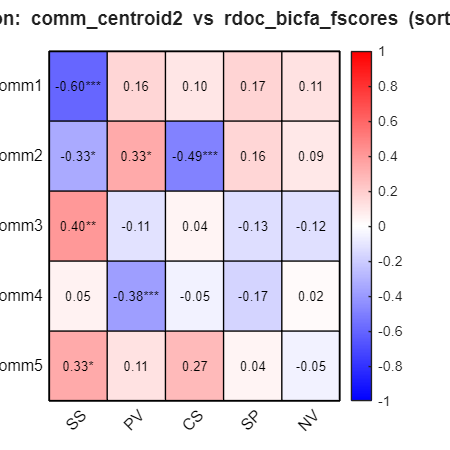

% save_figure_highres(gcf, 'figures/commcentroid_x_ddcbfafscores_sub2', 300);

plot_fixed_heatmap(R2_sorted, stars2_sorted, rdoc_labels_sorted, ...
    'Correlation: comm\_centroid2 vs rdoc\_bicfa\_fscores (sorted)', [800, 100], rwb_cmap);

% save_figure_highres(gcf, 'figures/commcentroid_x_rdocbicfafscores_sub2', 300);

## Extra plot: Visualizing average community centroid values across functional networks

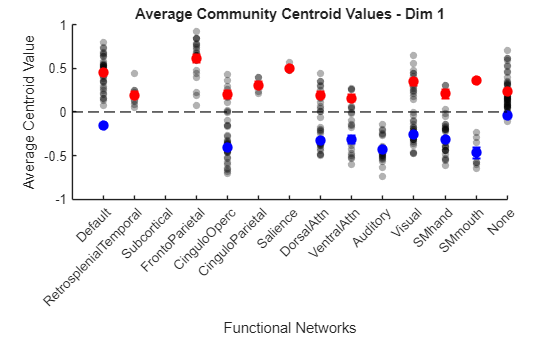

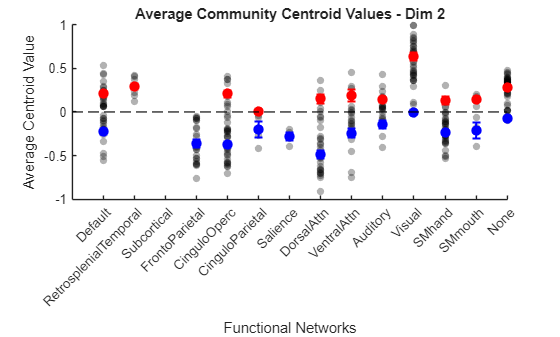

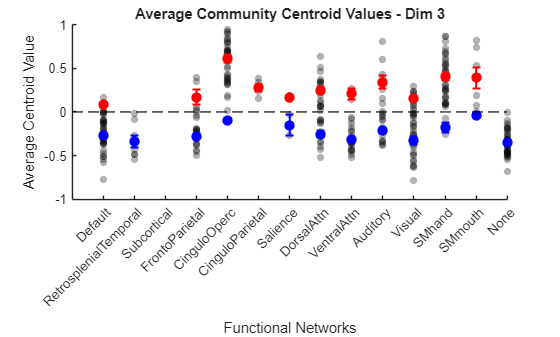

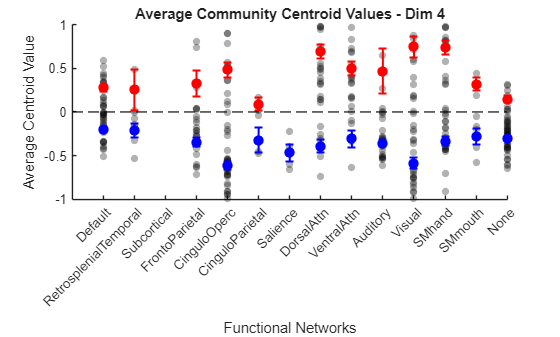

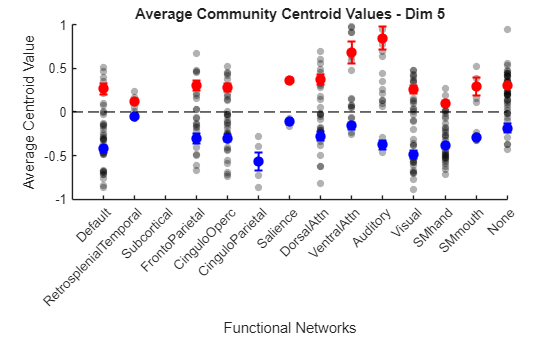

% Read Shine_375_labels.csv for reordering
opts1 = delimitedTextImportOptions("NumVariables", 8, "VariableTypes", [repelem("double",7), "string"]);
opts1.SelectedVariableNames = 8;
opts1.DataLines = [2, 348];
cifti2shineorder = readtable("Shine_375_labels.csv", opts1);
cifti2shineorder = str2double(cifti2shineorder{:,1});

% Reorder and subset
comm_centroid_shine = comm_centroid(:, cifti2shineorder);
comm_centroid_shine = comm_centroid_shine';

% Get networks
networks = parcelsT.Community(1:347, :);
% unique_networks = unique(networks, 'stable');
unique_networks = {'Default'; 'RetrosplenialTemporal'; 'Subcortical'; 'FrontoParietal'; 'CinguloOperc'; 'CinguloParietal'; 'Salience'; 'DorsalAttn'; 'VentralAttn'; 'Auditory'; 'Visual'; 'SMhand'; 'SMmouth'; 'None'}; %create an order of networks from higher-order transmodal networks to lower-order networks
num_networks = size(unique_networks, 1);

% Number of dimensions
num_features = size(comm_centroid_shine, 2);

% Preallocate for pos/neg values
network_pos_mean = zeros(num_networks, num_features);
network_pos_sem  = zeros(num_networks, num_features);
network_neg_mean = zeros(num_networks, num_features);
network_neg_sem  = zeros(num_networks, num_features);

% Compute mean and SEM for positive and negative values separately
for i = 1:num_networks
    network_idx = strcmp(networks, unique_networks{i});
    data = comm_centroid_shine(network_idx, :); % [num_nodes x num_features]
    
    for dim = 1:num_features
        values = data(:, dim);
        
        pos_vals = values(values > 0);
        neg_vals = values(values < 0);
        
        % Positive
        if ~isempty(pos_vals)
            network_pos_mean(i, dim) = mean(pos_vals);
            network_pos_sem(i, dim)  = std(pos_vals) / sqrt(length(pos_vals));
        else
            network_pos_mean(i, dim) = NaN;
            network_pos_sem(i, dim)  = NaN;
        end

        % Negative
        if ~isempty(neg_vals)
            network_neg_mean(i, dim) = mean(neg_vals);
            network_neg_sem(i, dim)  = std(neg_vals) / sqrt(length(neg_vals));
        else
            network_neg_mean(i, dim) = NaN;
            network_neg_sem(i, dim)  = NaN;
        end
    end
end

% Plotting
for dim = 1:num_features
    figure;
    hold on;
    
    % Plot individual data points
    for i = 1:num_networks
        network_idx = strcmp(networks, unique_networks{i});
        scatter(repmat(i, sum(network_idx), 1), comm_centroid_shine(network_idx, dim), ...
            30, 'k', 'filled', 'MarkerFaceAlpha', 0.3);
    end

    % Plot positive means and error bars
    errorbar(1:num_networks, network_pos_mean(:, dim), network_pos_sem(:, dim), ...
        'r', 'LineStyle', 'none', 'LineWidth', 1.5, 'CapSize', 6);
    scatter(1:num_networks, network_pos_mean(:, dim), 60, 'r', 'filled');

    % Plot negative means and error bars
    errorbar(1:num_networks, network_neg_mean(:, dim), network_neg_sem(:, dim), ...
        'b', 'LineStyle', 'none', 'LineWidth', 1.5, 'CapSize', 6);
    scatter(1:num_networks, network_neg_mean(:, dim), 60, 'b', 'filled');

    % Reference line
    yline(0, '--k', 'LineWidth', 1.2);

    % Axis settings
    xticks(1:num_networks);
    xticklabels(unique_networks);
    xtickangle(45);
    ylabel('Average Centroid Value');
    xlabel('Functional Networks');
    title(['Average Community Centroid Values - Dim ' num2str(dim)]);
    ylim([-1, 1]);

    hold off;
end

## Functions

function stars = makeStars(P)
    % makeStars: convert p-values to significance stars
    stars = strings(size(P));      % initialize with empty strings
    stars(P < 0.001) = "***";
    stars(P >= 0.001 & P < 0.01) = "**";
    stars(P >= 0.01  & P < 0.05) = "*";
end


function save_figure_highres(fig_handle, filename_base, dpi)
% SAVE_FIGURE_HIGHRES saves the given figure as high-resolution PDF and PNG.
% Usage:
%   save_figure_highres(fig_handle, 'figure_name', 300)

    if nargin < 3
        dpi = 300;  % default resolution
    end

    set(fig_handle, 'PaperPositionMode', 'auto');
    set(fig_handle, 'Units', 'Inches');
    pos = get(fig_handle, 'Position');
    set(fig_handle, 'PaperUnits', 'Inches');
    set(fig_handle, 'PaperSize', [pos(3), pos(4)]);

    % print(fig_handle, [filename_base '.pdf'], '-dpdf', ['-r' num2str(dpi)]);
    print(fig_handle, [filename_base '.png'], '-dpng', ['-r' num2str(dpi)]);
end

function plot_fixed_square_heatmap_with_stars(R, stars, xlabels, ylabels, ...
    title_str, fig_pos, cell_size, cmap, clim, outpath, lw)

    if nargin < 11
        lw = 0.5; % default MATLAB linewidth
    end

    [n_rows, n_cols] = size(R);

    % Sizes
    ax_width = n_cols * cell_size;
    ax_height = n_rows * cell_size;
    cb_width = 20;
    margin = 50;
    fig_width = ax_width + cb_width + 2 * margin;
    fig_height = ax_height + 2 * margin;

    fig = figure('Units','pixels','Position',[fig_pos, fig_width, fig_height], ...
                 'Resize','off','Color','w');

    ax = axes('Units','pixels','Position',[margin, margin, ax_width, ax_height], ...
              'Parent',fig);

    imagesc(ax,R);
    colormap(ax,cmap);
    caxis(ax,clim);

    set(ax,'DataAspectRatio',[1 1 1]);
    xticks(ax,1:n_cols); yticks(ax,1:n_rows);
    xticklabels(ax,xlabels); yticklabels(ax,ylabels);
    xtickangle(ax,45);
    set(ax,'FontSize',12,'LineWidth',lw,'Box','on','TickLength',[0 0]);

    hold(ax,'on');
    for i = 0:n_rows
        line(ax,[0.5, n_cols+0.5],[i+0.5, i+0.5],'Color','k','LineWidth',lw);
    end
    for j = 0:n_cols
        line(ax,[j+0.5, j+0.5],[0.5, n_rows+0.5],'Color','k','LineWidth',lw);
    end

    % Overlay values with stars
    for i = 1:n_rows
        for j = 1:n_cols
            txt = sprintf('%.2f%s', R(i,j), stars(i,j));
            text(ax,j,i,txt,'HorizontalAlignment','center','Color','black','FontSize',10);
        end
    end
    hold(ax,'off');

    title(ax,title_str,'FontSize',14,'Units','normalized','Position',[0.5,1.05,0]);

    cb = colorbar(ax);
    cb.Units = 'pixels';
    cb.Position = [margin+ax_width+10, margin, cb_width, ax_height];

    if ~isempty(outpath)
        print(fig,outpath,'-dpng','-r300');
    end
end


function plot_fixed_heatmap(R, stars, xlabels, title_str, fig_pos, cmap)
    [n_rows, n_cols] = size(R);

    % Set cell size
    cellWidth = 70;
    cellHeight = 70;

    figWidth = n_cols * cellWidth;
    figHeight = n_rows * cellHeight;

    % Create fixed-size figure
    fig = figure('Units', 'pixels', ...
        'Position', [fig_pos, figWidth + 100, figHeight + 100], ...
        'Resize', 'off', ...
        'Color', 'w');

    % Create axes
    ax = axes('Units', 'pixels', ...
        'Position', [50, 50, figWidth, figHeight]);

    % Plot heatmap
    imagesc(R);
    colormap(ax, cmap);
    caxis(ax, [-1 1]);

    % Add colorbar with border
    cb = colorbar(ax);
    cb.Box = 'on';

    % Draw grid lines (cell borders)
    hold on;
    for i = 0:n_rows
        line([0.5, n_cols + 0.5], [i + 0.5, i + 0.5], 'Color', 'k', 'LineWidth', 0.5);
    end
    for j = 0:n_cols
        line([j + 0.5, j + 0.5], [0.5, n_rows + 0.5], 'Color', 'k', 'LineWidth', 0.5);
    end
    hold off;

    % Overlay correlation values with stars
    for i = 1:n_rows
        for j = 1:n_cols
            text(j, i, sprintf('%.2f%s', R(i,j), stars(i,j)), ...
                'HorizontalAlignment', 'center', ...
                'Color', 'k', ...
                'FontSize', 10);
        end
    end

    % Show axis labels, but remove tick marks
    set(ax, 'XTick', 1:n_cols, ...
            'YTick', 1:n_rows, ...
            'XTickLabel', xlabels, ...
            'YTickLabel', "Comm" + (1:n_rows), ...
            'TickLength', [0 0], ...
            'Box', 'on', ...
            'FontSize', 12, ...
            'XColor', 'k', ...
            'YColor', 'k');

    % Optional: rotate x-axis labels for readability
    xtickangle(ax, 45);

    % Title
    title(title_str, 'FontSize', 14, 'Units', 'normalized', ...
        'Position', [0.5, 1.05, 0]);
end